## ECEN 142L Communications and Networking Lab

## Lab 6: Code Division Multiple Access

## **Dylan Thornburg & Ricky Xie**

Last week we took a look at two common multiple access techniques, TDMA and FDMA. Recall the example we used to motivate their use: a room where many people are talking simultaneously. Using that analogy, TDMA would be only 1 person speaking at a time, and FDMA would be people talking using different pitches. You might be able to imagine a 3rd way to keep the conversation coherent - use more than one language, which is a topic we will explore today with CDMA.

Today’s Objective: Learn more about multiple access by exploring CDMA.

## Part 1: CDMA encoding

Code Division Multiple Access (CDMA) is a channel access method that uses orthogonal codes to spread out the signal bandwidth. Unlike TDMA and FDMA, every communicator in a CDMA system is allocated the entire available spectrum at all times.

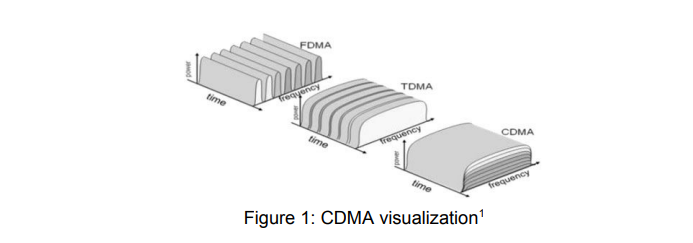

CDMA Uplink is a bit more complicated (asynchronous communication and pseudo-random user codes) so today we will focus only on CDMA downlink.

Let's get started builded our own version of CDMA to see how it's different from the other multiple access techniques.

**Step 1:**

Let’s begin by creating our spreading codes. In our system, each user will get a unique code to modulate the data they wish to transmit. We don’t want the transmissions to interfere with one another, so the codes need to be orthogonal, i.e., the dot product of any two codes must equal zero.

Luckily for us, some smart mathematicians created Walsh-Hadamard matrices, which are matrices where all the rows and columns are orthogonal to each other, and they were kind enough to give us a formula, which is:

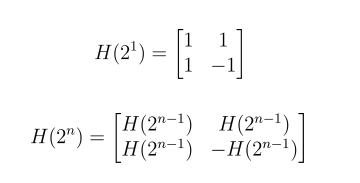

Write a function WalshHadamard(n) that returns a valid Walsh-Hadamard matrix of size 2^n.

(Hint: Matlab allows you to define matrices recursively!)

Once you are finished, create a Walsh-Hadamard matrix with n=4. Select any 2 rows or columns (they can't be the same) and check to make sure they are orthogonal. Demo your function to the TA.

clear;
clc;
close all;

n = 4;
WH = WalshHadamard(n);

code1_test = WH(1,:);
code2_test = WH(16,:);

orthogonality_check = dot(code1_test, code2_test)

orthogonality_check = 0

With your n=4 matrix, how many users can your system support?

**We can support 16 users.**

**Step 2:**

Let’s now get our data. We will first need to create a data signal for each user. To keep things interesting, we will be using a digital signal today instead of analog signals like we used for TDMA and FDMA, though CDMA isn’t limited to only digital signals.

Create two signals, user1 and user2, that are randomly distributed binary arrays of length 10. Reference this page for help: Uniformly distributed pseudorandom integers - MATLAB randi

In communications, we typically will change zero values to -1, so lets quickly do that as well. Past the following code into your program:

        user1(user1==0) = -1;

        user2(user2==0) = -1;

Finally, create 2 variables, code1 and code2, and fill them with 2 different spreading codes from your Walsh-Hadamard matrix.

user1 = randi([0 1], 1, 10);
user2 = randi([0 1], 1, 10);

user1(user1==0) = -1;
user2(user2==0) = -1;

code1 = code1_test;
code2 = code2_test;

**Step 3:**

We can now perform the CDMA step. Here is how it looks for a single step:

        user1(i)*code1 + user2(i)*code2;

In every step, one sample of data from each user is modulated by its own spreading code, and the results are added together. Notice that for each data sample, we generate 16 CDMA samples.

Write a loop to perform the CDMA step for 10 steps, one for each sample in our user data arrays. Be careful with the indexing! The output array should be 160 samples long. Plot the generated signal and demo to the TA.

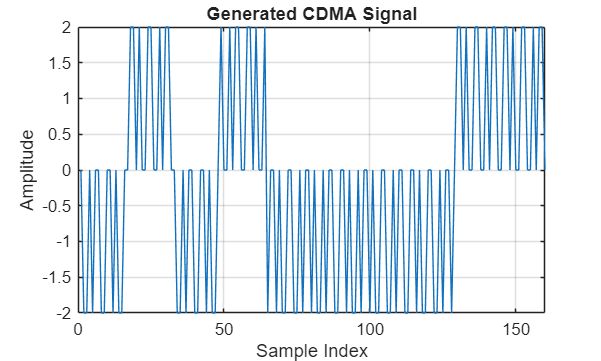

xCDMA = zeros(1,160);

for i = 1:10
    idx = (i-1)*16 + 1 : i*16;
    xCDMA(idx) = user1(i)*code1 + user2(i)*code2;
end

figure;
plot(xCDMA);
xlabel('Sample Index');
ylabel('Amplitude');
title('Generated CDMA Signal');
grid on;

## Part 2: CDMA decoding

In our previous decoders, we implicitly assumed that our channel was wired because the only addition we made to the signal going in to the receiver was adding some white noise. However, wireless receivers suffer from the multipath problem - the signal received will have come from multiple paths because the signal will reflect and refract off of objects.

Today, we will consider the multipath problem by creating a rake receiver, which isn't as scary as it sounds!

**Step 1:**

Lets first create a multipath signal to work on. We will keep it relatively simple, with our new signal being unity gain at time t=0, and 0.5 gain at time t=3.

Create a new signal, xCDMA_m, that is the multipath signal we defined above. To properly create the new signal, we will need to zero pad our original CDMA signal, and add a shifted version of itself back to the original.

Plot the new signal and compare it against the original. What does it look like? Demo your plot to the TA.

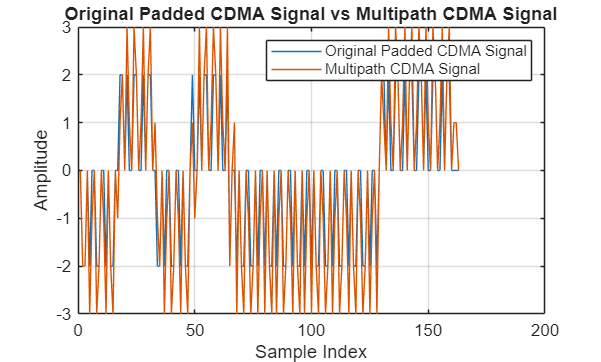

xCDMA_padded = [xCDMA zeros(1,3)];

shifted = [zeros(1,3) 0.5*xCDMA];

xCDMA_m = xCDMA_padded + shifted;

figure;
plot(xCDMA_padded);
hold on;
plot(xCDMA_m);
hold off;
legend('Original Padded CDMA Signal','Multipath CDMA Signal');
xlabel('Sample Index');
ylabel('Amplitude');
title('Original Padded CDMA Signal vs Multipath CDMA Signal');
grid on;

**It's the same signal added with a time shifted (3) and half gained (.5x multiplier) version of it added on which is exactly what's expected. Now instead of just 2,0, and -2 being possible ampltidue values, the half signal addition and time difference casues 3,2,1,0,-1,-2, and -3 to be possible amplitude values.**

**Step 2:**

Now we will make a rake receiver to decode the multipath signal. A rake receiver uses multiple sub-receivers called fingers that can sift out the different multipath components of the signal (much like a rake). Here is what that looks like in code form:

        rx_user1(i) = sum((xCDMA_m(1:16) .* code1) + (0.5*xCDMA_m(4:19) .* code1));

In this snippet (which corresponds to the first step) we have 2 fingers, one for each of the multipath components. These components are demodulated and correlated to produce the final received sample.

Create 2 variables, rx_user1 and rx_user2, to store the received samples. Using the code above as a reference, write a loop to apply our rake receiver to the xCDMA_m signal. (Hint: if you do it correctly, the results won’t be equal to user1 and user2 quite yet, we will do that in the next step).

rx_user1 = zeros(1,10);
rx_user2 = zeros(1,10);

for i = 1:10
    idx = (i-1)*16 + 1;
    rx_user1(i) = sum((xCDMA_m(idx:idx+15) .* code1) + (0.5*xCDMA_m(idx+3:idx+18) .* code1));
    rx_user2(i) = sum((xCDMA_m(idx:idx+15) .* code2) + (0.5*xCDMA_m(idx+3:idx+18) .* code2));
end

rx_user1

rx_user1 =     33   -31    33    36    35    37    34   -32    32   -33


user1

user1 =      1    -1     1     1     1     1     1    -1     1    -1


rx_user2

rx_user2 =     27   -27   -23   -24   -25    25    26   -28    28   -27


user2

user2 =      1    -1    -1    -1    -1     1     1    -1     1    -1


**Step 3:**

As you might have noticed, the results from step 2 don’t exactly match user1 and user2. The correlation step gives us back numbers somewhere between 20 and 50 depending on the input signal. But if you look closely, the sign should be correct for every sample! To get back the correct samples, we need to only preserve the sign of each sample, which is what the signum function does.

Using Sign function (signum function) - MATLAB sign for help, apply the signum function to your results from step 2. Check each output array against user1 and user2 to make sure they match. Show your results to the TA.

rx_user1_decoded = sign(rx_user1);
rx_user2_decoded = sign(rx_user2);

user1_match = isequal(rx_user1_decoded, user1)

user1_match = logical
   1


user2_match = isequal(rx_user2_decoded, user2)

user2_match = logical
   1


## Part 3: Power control

Let’s go back to our example of people talking in a room. In TDMA, only one person is talking at a time, and in FDMA, people are using different pitches to converse. In both of these scenarios, it doesn't matter so much how loud the people are talking as long as they are loud enough to be heard.

In CDMA, signal power is a harder problem. Since every user gets to talk at the same time, if someone is shouting and someone else is whispering, the person whispering won't be heard at all. This problem shows up in CDMA wireless - if a user is farther away or has a weaker transmission power, it might be drowned out by other users, so we need to control the transmission power of every user so that the power at the receiver is more of less the same.

Lets simulate the power control process to see what the results are.

**Step 1:**

Head over to the camino page and download two scripts - jakes.m and PowerControlFunc.m. Save these scripts in the same directory as your program for this lab.

Step 2:

Here is an example usage of the PowerControlFunc script:

        [timeUpdate, TxPowdB, SNRdB] = PowerControlFunc(2.4e9, 2, 5e-3);

        figure;

        plot(timeUpdate, TxPowdB(1:length(timeUpdate))); title('Tx Power (dB)');

        figure;

        plot(SNRdB); title('SNR (dB)');

Run this code and inspect the results. You can see the function takes 3 parameters, which are:

1. The carrier frequency in Hz. In this example, the frequency is 2.4 GHz, which is one of the frequencies used by WiFi.

2. The velocity of movement in meters per second. In this example, the velocity is 2 m/s which is about 4 mph (walking speed).

3. The power update interval in seconds. In this example, the interval is 5 milliseconds.

The first plot is the transmit power, which moves around quite a bit trying to offset the motion of the transmitter. The second plot is the SNR, which if you were to fit a line of average value to, it would be pretty flat, which means we did a decent job.

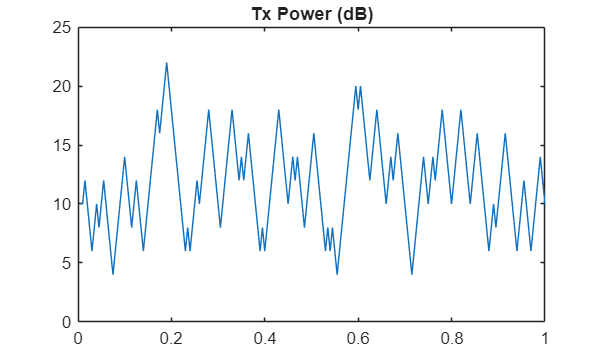

[timeUpdate, TxPowdB, SNRdB] = PowerControlFunc(2.4e9, 2, 5e-3);

figure;
plot(timeUpdate, TxPowdB(1:length(timeUpdate))); title('Tx Power (dB)');

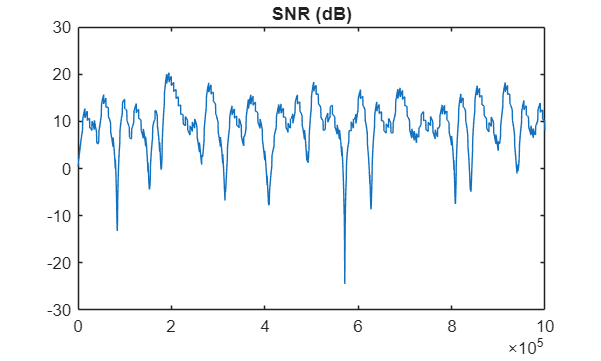


figure;
plot(SNRdB); title('SNR (dB)');

**Step 3:**

Pick two scenarios for a transmitter, research the parameters that would be in use, run them through the PowerControlFunc, and comment on their plots.

For example, I might pick 4G LTE on a bullet train. With a bit of googling, I would find that Verizon 4G is typically using 750 MHz, and a bullet train is around 130 m/s.

(Latency is typically 5 ms, but try another value and see what happens)

Comment on your plots - do they match what you expected for the scenario you picked? Show your results from Part 3 to the TA.

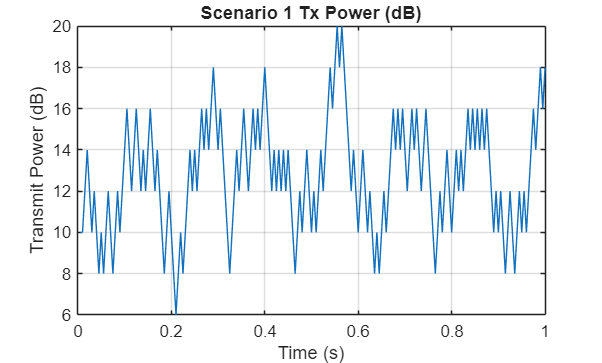

% LTE example from lab
f1 = 750e6; 
v1 = 130; 
l1 = 5e-3;

[timeUpdate1, TxPowdB1, SNRdB1] = PowerControlFunc(f1, v1, l1);

figure;
plot(timeUpdate1, TxPowdB1(1:length(timeUpdate1)));
title('Scenario 1 Tx Power (dB)');
xlabel('Time (s)');
ylabel('Transmit Power (dB)');
grid on;

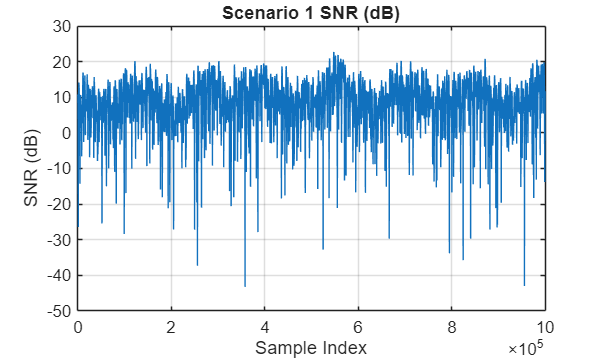


figure;
plot(SNRdB1);
title('Scenario 1 SNR (dB)');
xlabel('Sample Index');
ylabel('SNR (dB)');
grid on;

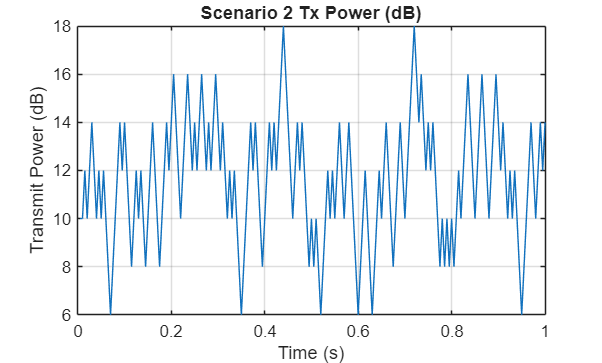

f2 = 750e6; 
v2 = 1300;  %10x
l2 = 5e-3;

[timeUpdate2, TxPowdB2, SNRdB2] = PowerControlFunc(f2, v2, l2);

figure;
plot(timeUpdate2, TxPowdB2(1:length(timeUpdate2)));
title('Scenario 2 Tx Power (dB)');
xlabel('Time (s)');
ylabel('Transmit Power (dB)');
grid on;

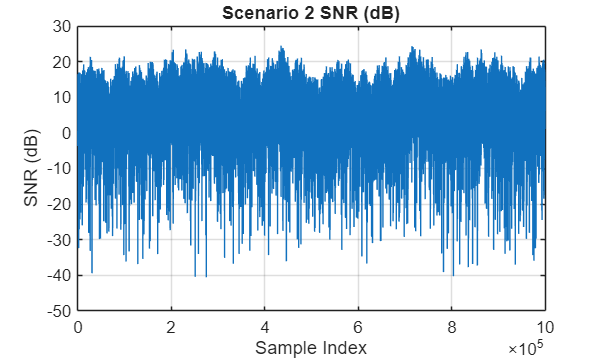


figure;
plot(SNRdB2);
title('Scenario 2 SNR (dB)');
xlabel('Sample Index');
ylabel('SNR (dB)');
grid on;

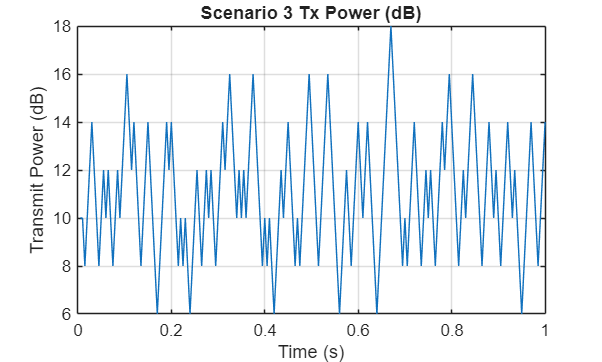

f3 = 750e9; %GHz instead of MHz
v3 = 130; 
l3 = 5e-3;

[timeUpdate3, TxPowdB3, SNRdB3] = PowerControlFunc(f3, v3, l3);

figure;
plot(timeUpdate3, TxPowdB3(1:length(timeUpdate3)));
title('Scenario 3 Tx Power (dB)');
xlabel('Time (s)');
ylabel('Transmit Power (dB)');
grid on;

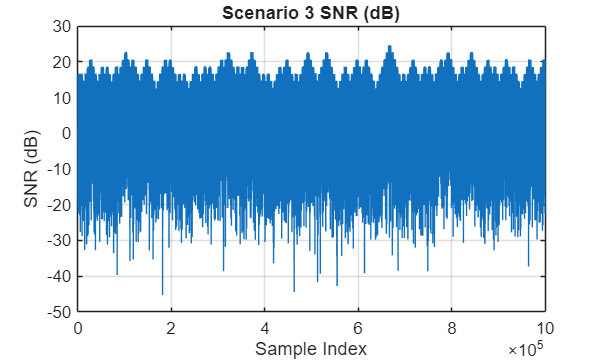


figure;
plot(SNRdB3);
title('Scenario 3 SNR (dB)');
xlabel('Sample Index');
ylabel('SNR (dB)');
grid on;

**These graphs match for the scenarios we picked. When our frequency and velocity were larger, our SNR ratio was much greater. This makes sense because doppler shift adds noise (increasing SNR), and doppler shift is defined with this equation:**

## Report

Submit your codes and answers to questions on camino. In addition, discuss the following questions with your partner and attach your answers to the end of your report.

1. What did you observe from the experiments?

**We observed CDMA in action and how it modulates signals to accomodate multiple users. We also observed how CDMA is affected during multipath. In terms of power control, we can the impact changes in frequency and velocity has on SNR.**

2. If you could expand this experiment how would you do it?

**To expand, we could possible test with more users to see how WalshHadamard can accomodate multiple users. Possibly add another example where we change the latency in Part 3.**

3. How does the experiment relate to the course topic?

**It directly relates to CDMA since we used that in lab, as well as exploring doppler shift which is another lecture concept.**

4. What did you learn from the experiment?

**Frequency and device velocity play a big role in determing SNR. With encodings, CDMA can support a plethora of users quite easily when compared to FDMA and TDMA.**